# Analyzing phases

## Recollect all data


load('results_BrainBonus2.mat')
recollect_data

## basic all power display

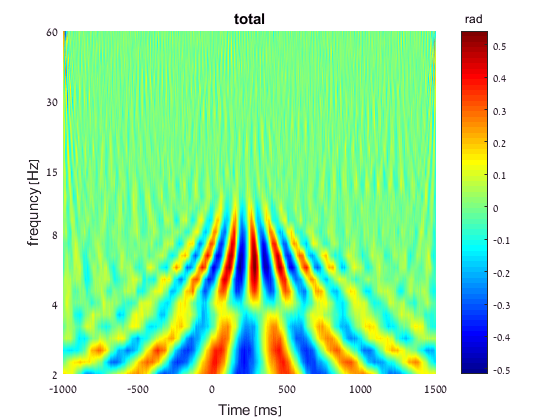

show_spectrum(squeeze(mean(total_phases(:,:,:,:),4)), times, freqs, 'surf', 'total', true, 'rad')

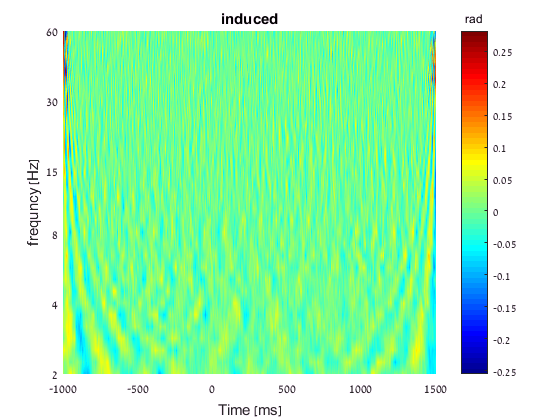

show_spectrum(squeeze(mean(total_sub_phases(:,:,:,:),4)), times, freqs, 'surf', 'induced', true, 'rad')

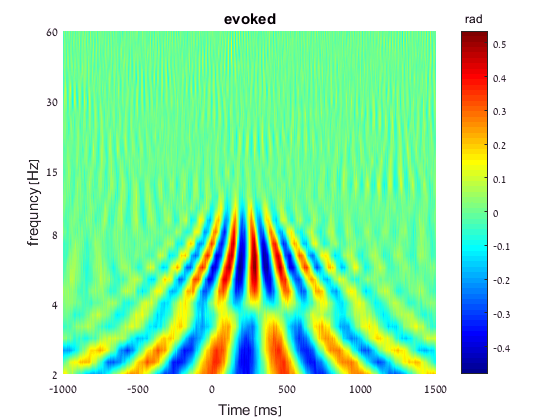

show_spectrum(squeeze(mean(total_phases(:,:,:,:)-total_sub_phases(:,:,:,:),4)), times, freqs, 'surf', 'evoked', true, 'rad')

## using mean angle:

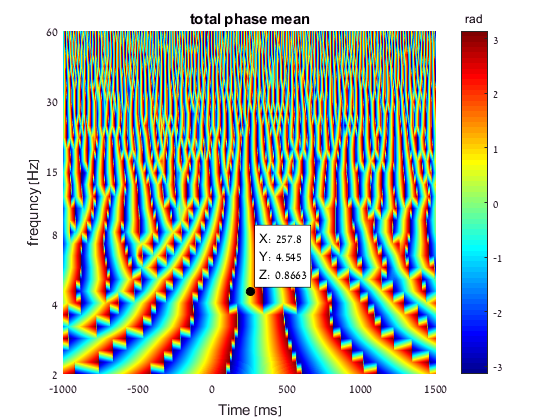

show_spectrum(squeeze(circ_mean(total_phases(:,:,:,:),[],4)), times, freqs, 'surf', 'total phase mean', true, 'rad')

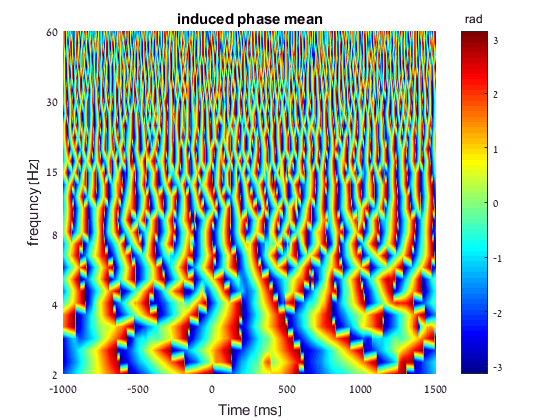

show_spectrum(squeeze(circ_mean(total_sub_phases(:,:,:,:),[],4)), times, freqs, 'surf', 'induced phase mean', true, 'rad')

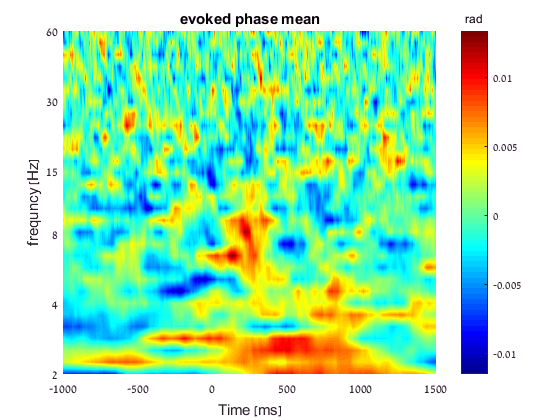

show_spectrum(squeeze(circ_mean(total_phases-total_sub_phases,[],4)), times, freqs, 'surf', 'evoked phase mean', true, 'rad')

## R (1-Var) = Mean Phase-Coherence

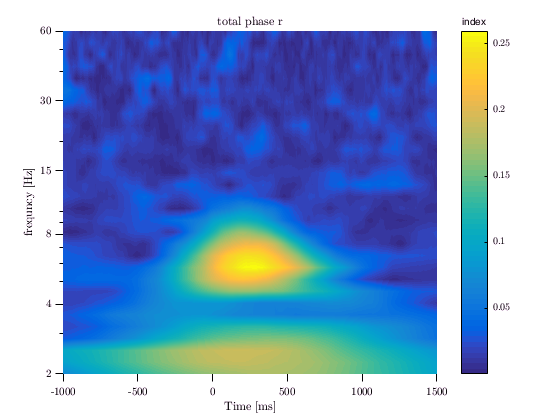

figure;
show_spectrum(squeeze(circ_r(total_phases(:,:,:,:),[],[],4)), times, freqs, 'surf', 'total phase r', true, 'index')

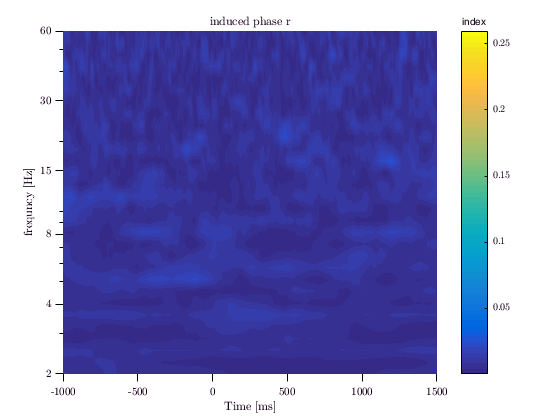

Ca = caxis;
show_spectrum(squeeze(circ_r(total_sub_phases(:,:,:,:),[],[],4)), times, freqs, 'surf', 'induced phase r', true, 'index')
caxis(Ca);

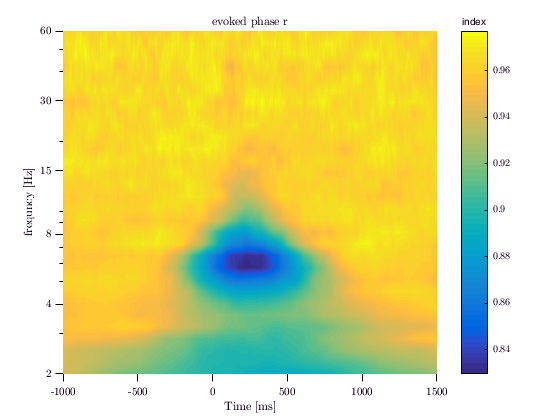

show_spectrum(squeeze(circ_r(total_phases-total_sub_phases,[],[],4)), times, freqs, 'surf', 'evoked phase r', true, 'index')

std

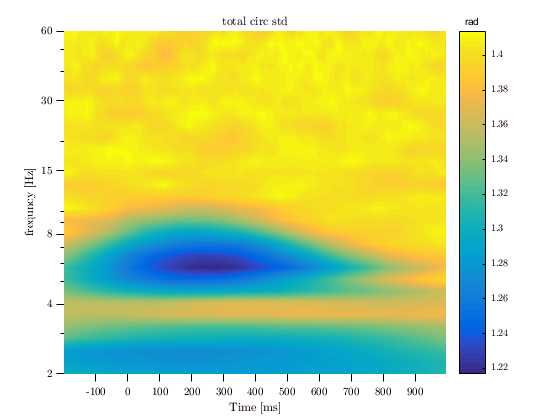

figure;
show_spectrum(squeeze(circ_std(total_phases(:,:,u,:),[],[],4)), t, freqs, 'surf', 'total circ std',true, 'rad')

Ca = caxis;

Ca =     1.2168    1.4140


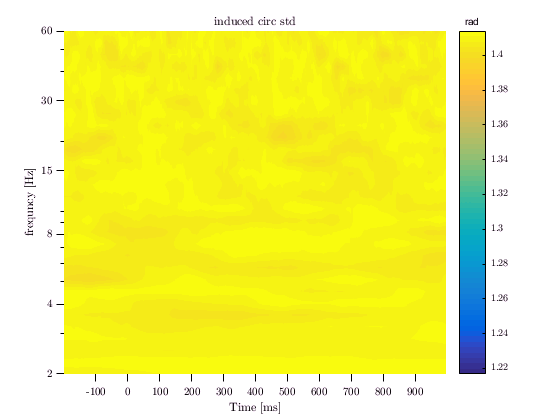

show_spectrum(squeeze(circ_std(total_sub_phases(:,:,u,:),[],[],4)), t, freqs, 'surf', 'induced  circ std',true, 'rad')
caxis(Ca);

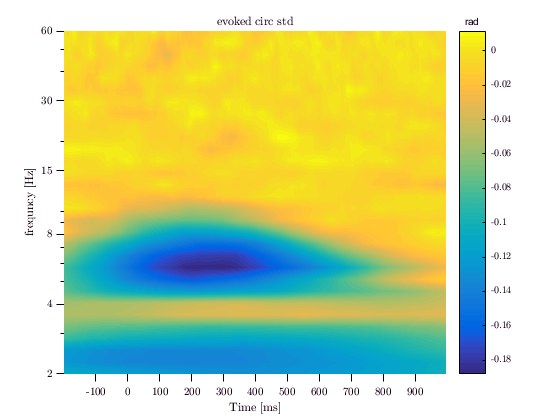

show_spectrum(squeeze(circ_std(total_phases(:,:,u,:),[],[],4)-circ_std(total_sub_phases(:,:,u,:),[],[],4)), t, freqs, 'surf', 'evoked  circ std',true, 'rad')

phases_stds= [];
for ii = 1:length(results)
    phases_stds(:,:,ii) = squeeze(circ_std(results{ii}.phases(:,:,u,:),[],[],4));
end

figure;
permutest_2dplot(phases_stds,median(phases_stds(:)),[],0.0001,1e4,true,[],[],t, freqs);

Cluster 1: time points 3 to 7443, t-sum = -3467.08, p-value = 9.999e-05.
Cluster 2: time points 1451 to 6161, t-sum = -3219.6, p-value = 9.999e-05.


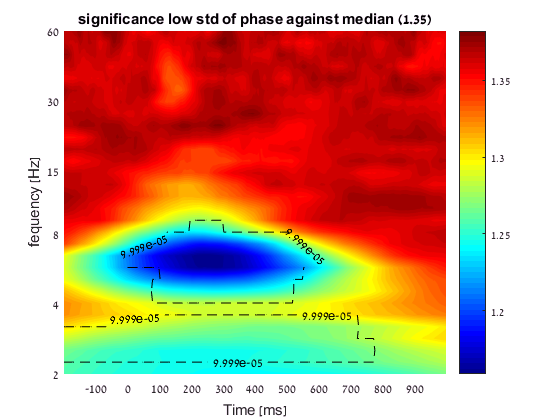

title(sprintf('significance low std of phase against median (%.3g)', median(phases_stds(:))))

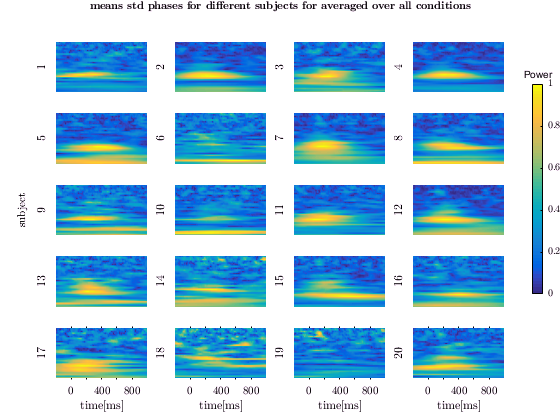

figure
num_columns = 4;
ha = tight_subplot(length(results)/num_columns ,num_columns ,0.05,0.1,[0.1, 0.1]);
for ii = 1:length(results)

    %     subplot(length(results),1,ii)
    axes(ha(ii));
    subj_std_phase = squeeze(circ_std(results{ii}.phases(:,:,u,:),[],[],4));
    erps = mean(results{ii}.erps,2);    
    args = {t,freqs,subj_std_phase };

    pcolor(args{:})%,'edgecolor','none');
    caxis([min(subj_std_phase(:)) max(subj_std_phase(:))]);
    view(0,90);
    axis tight;
    shading interp; %colormap(parula(128));
    ylabel(ii)
    set(gca,'XTick',[]);
    set(gca,'YTick',[]);
    
    set(gca,'yscale','log')


%     caxis([min(trials(:)), max(trials(:))])
end

% axes(ha(floor(length(results)/2)))
hy = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text(0.04, 0.5,'subject','VerticalAlignment' ,'middle','HorizontalAlignment', 'center', 'Rotation', 90);

for ii=length(results)-num_columns+1:length(results)
    axes(ha(ii))
    xlabel time[ms]
    set(gca,'XTickMode', 'auto')
end

%title for the figure
ha = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text(0.5, 1,sprintf('\\bf %s', 'means std phases for different subjects for averaged over all conditions'),'HorizontalAlignment' ,'center','VerticalAlignment', 'top');

h = colorbar;
title(h,'Power');
set(h, 'Position', [.95 0.3 0.02 0.5])

## Theta for every subject

- Generate Theta Data

theta_phases = [];
theta_phases_subjects = cell(1,length(results));
freq_min = 4.5;
freq_max = 8;
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    theta_phases_subjects{subj_ind} = theta_phases_subject;
    theta_phases(subj_ind,:) = circ_mean(theta_phases_subject,[],2);
end

erp_theta_phases = [];
for subj_ind = 1:length(results)
    erp_theta_phases(subj_ind,:) = get_hilbert_phase(mean(results{subj_ind}.trials,3), freq_min, freq_max, SamplingInterval);
end


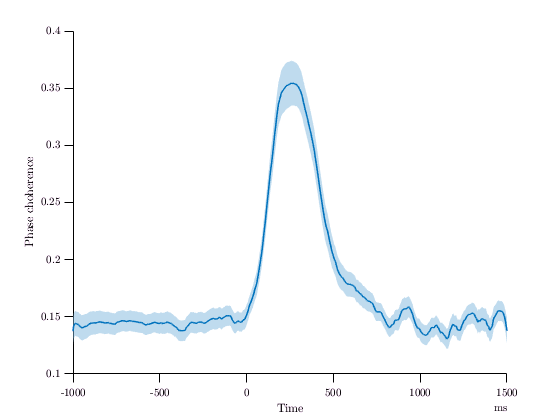

theta_phases_r = zeros([length(times), max(condition_positions), length(results)]);
freq_min = 4.5;
freq_max = 8;
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    for cond_ind = 1:size(theta_phases_r,2)
        theta_phases_r(:,cond_ind,subj_ind) = circ_r(theta_phases_subject(:,results{subj_ind}.condition_positions == cond_ind),[],[],2);
    end
end
varplot(times,theta_phases_r(:,:)) 
xlabel Time
xunits ms
ylabel 'Phase choherence'

t_maxs = zeros(1,20);
jitters_estimate = zeros(1,20);
t_min_max = [100, 500];
mask = t_min_max(1)<times & times<t_min_max(2);
for subj = 1:20
% [~,t_ind_subj] = max(circ_r(theta_phases_subjects{subj},[],[],2));
    [~,t_ind_subj] = max(mean(theta_phases_r(:,:,subj) ,2).*mask');
    subj_theta_phases = cell2mat(cellfun(@(X) X(t_ind_subj,:),theta_phases_subjects(subj), 'UniformOutput' ,false));
    % subj_theta_phases = theta_phases_subjects{subj};
    [~, kappa] = circ_vmpar(subj_theta_phases);

    t_maxs(subj) = times(t_ind_subj);
    jitters_estimate(subj) = 1/sqrt(kappa) * pi/2 / freq_mean / SamplingInterval * 1e6;
end
fprintf('jitter estimate is %.0f±%.0f [ms] at t ~ %.0f±%.0f', ...
    mean(jitters_estimate), std(jitters_estimate), mean(t_maxs), std(t_maxs))

jitter estimate is 83±21 [ms] at t ~ 275±79

theta_freqs = [];
theta_freqs_subjects = cell(1,length(results));
for subj_ind = 1:length(results)
    theta_phases_subject = get_hilbert_phase(results{subj_ind}.trials, freq_min, freq_max, SamplingInterval);
    theta_freqs_subjects{subj_ind} = srate*1000/(2*pi)*diff(unwrap(theta_phases_subject));    
    theta_freqs(subj_ind,:) = mean(theta_freqs_subjects{subj_ind},2);
end


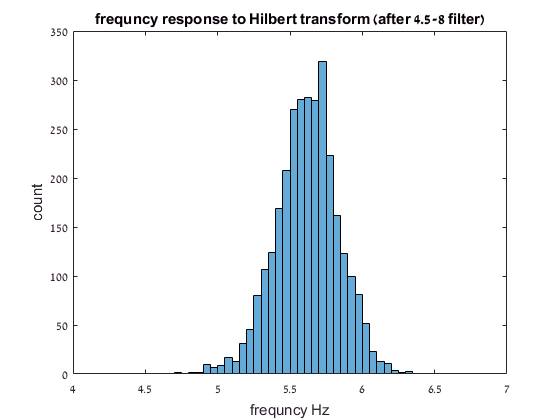

histogram(theta_freqs(:,0<times & times<600))
xlabel 'frequncy Hz'
ylabel count
title 'frequncy response to Hilbert transform (after 4.5-8 filter)'

fprintf('mean freq: %.3g',mean(paren(theta_freqs(:,0<times & times<600),':')))

mean freq: 5.62

fprintf('freq 90%% range: %.3g - %.3g',...
                prctile(paren(theta_freqs(:,0<times & times<600),':'),[5 95]))

freq 90% range: 5.25 - 5.97

## Polar Histogram

all phases together

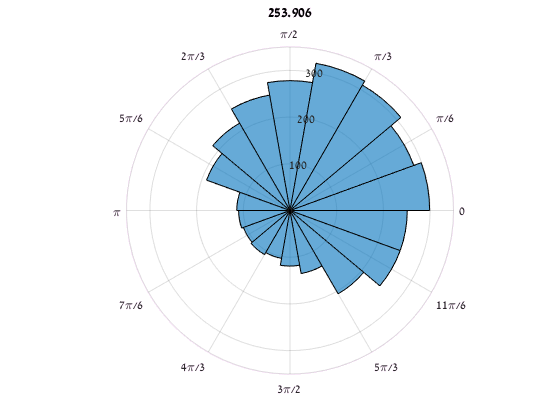

t0 = 250;
t_ind = find(times>t0,1);

figure
polarhistogram(cell2mat(cellfun(@(X) X(t_ind,:),theta_phases_subjects, 'UniformOutput' ,false)))
pax = gca;
pax.ThetaAxisUnits = 'radians';
%     pax.ThetaTick = linspace(0,2*pi,5);
% pax.GridLineStyle = ':';
title(times(t_ind))

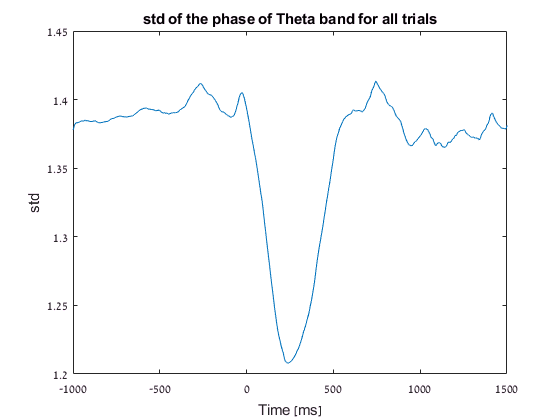


figure;
plot(times, circ_std(cell2mat(theta_phases_subjects),[],[],2))
xlabel 'Time [ms]'
ylabel std
title 'std of the phase of Theta band for all trials'

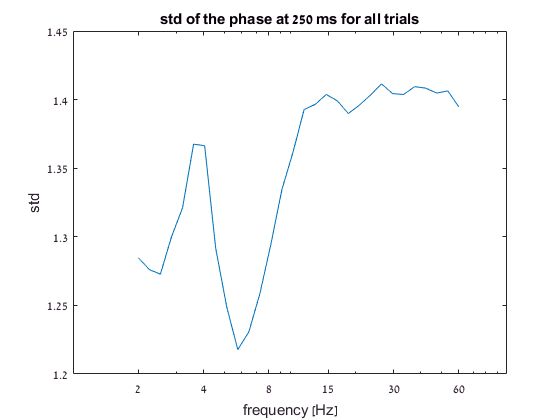


figure;
plot(freqs, squeeze(circ_std(total_phases(:,:,find(times>250,1),:),[],[],4)))
set(gca,'xscale','log')
set(gca,'XTick',round(logspace(log10(min(freqs)), log10(max(freqs)), 6)))
xlabel 'frequency [Hz]'
ylabel std
title 'std of the phase at 250 ms for all trials'

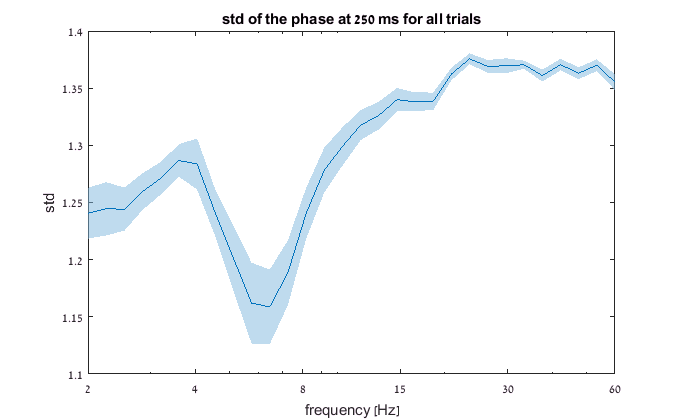

figure;
varplot(freqs, squeeze(phases_stds(:,find(t>250,1),:)))
set(gca,'xscale','log')
set(gca,'XTick',round(logspace(log10(min(freqs)), log10(max(freqs)), 6)))
xlabel 'frequency [Hz]'
ylabel std
title 'std of the phase at 250 ms across subjects'

histogram of jitters

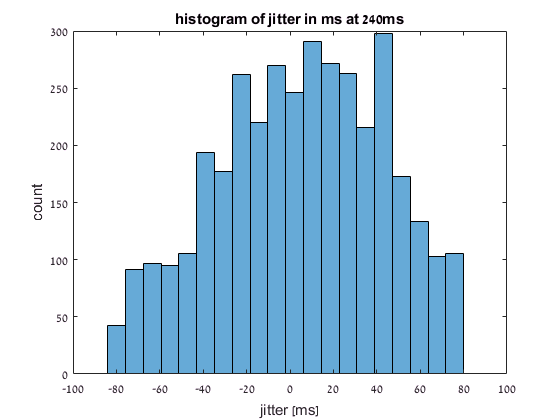

total_phase_shifts = get_hilbert_phase_shift(norm_trials, 4.5, 8, SamplingInterval);
figure;
histogram(total_phase_shifts(find(times>240,1),:)/srate,20)
xlabel 'jitter [ms]'
ylabel count
title 'histogram of jitter in ms at 240ms'

each subject independently

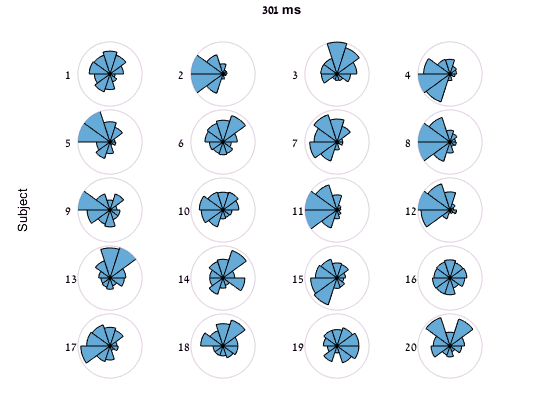

figure;
show_polar_hists_tight(cellfun(@(X) X(t_ind,:),theta_phases_subjects, 'UniformOutput' ,false), ...
    4,num2str(times(t_ind),'%.3g ms'))

different times

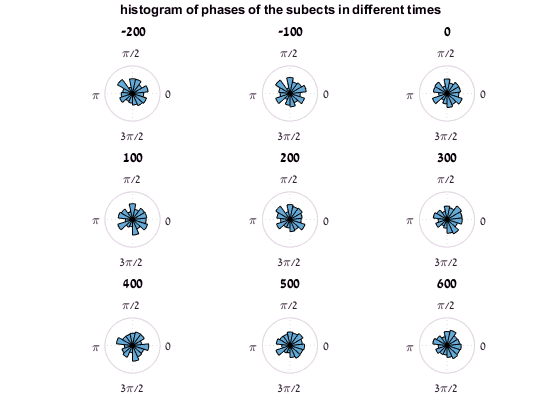

figure;
t0s = -200:100:600;
for ii = 1:length(t0s)
    subplot(3,3,ii)
    t_ind = find(times>t0s(ii),1);
    polarhistogram(cell2mat(cellfun(@(X) X(t_ind,:),theta_phases_subjects, 'UniformOutput' ,false)), ...
        15, 'Normalization','probability')
    pax = gca;
    pax.ThetaAxisUnits = 'radians';
    pax.ThetaTick = linspace(0,2*pi,5);
    pax.RLim = [0, 0.15];
    pax.RTick = [];
%     pax.ThetaTick = [];
    pax.GridLineStyle = ':';

    %     circ_plot2(theta_phases(:,find(times>t0s(ii),1)),'compass','-k',true,'linewidth',2,'color','g');
    title(t0s(ii))
end
title_subplots 'histogram of phases of all the subects in different times'

## Compass of the mean of the Theta

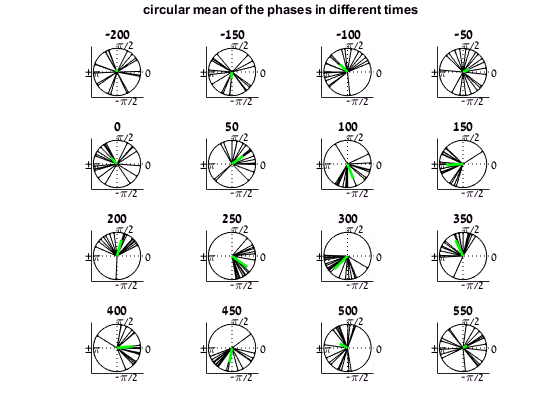

figure;
t0s = -200:50:550;
for ii = 1:length(t0s)
    subplot(4,4,ii)
    circ_plot2(theta_phases(:,find(times>t0s(ii),1)),'compass','-k',true,'linewidth',2,'color','g');
    title(t0s(ii))
end
title_subplots 'circular mean of the phases in different times'

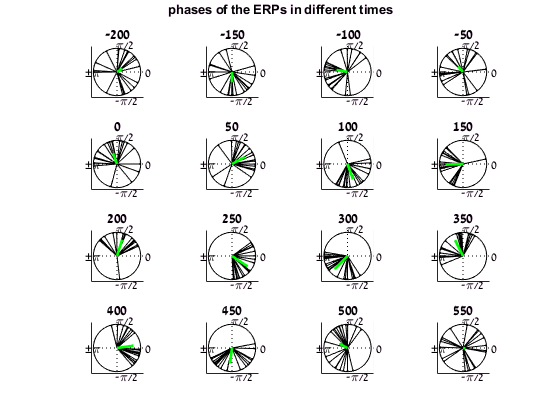


figure;
for ii = 1:length(t0s)
    subplot(4,4,ii)
    circ_plot2(erp_theta_phases(:,find(times>t0s(ii),1)),'compass','-k',true,'linewidth',2,'color','g');
    title(t0s(ii))
end
title_subplots 'phases of the ERPs in different times'

## Final Image

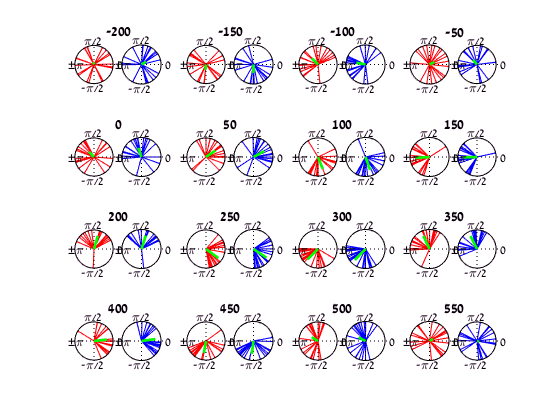

figure;
t0s = -200:50:550;
for ii = 1:length(t0s)
    subplot(4,8,ii*2-1)
    circ_plot2(theta_phases(:,find(times>t0s(ii),1)),'compass','-r',true,'linewidth',2,'color','g');
    subplot(4,8,ii*2)
    h =circ_plot2(erp_theta_phases(:,find(times>t0s(ii),1)),'compass','-b',true,'linewidth',2,'color','g');
    h.Position = h.Position + [-0.015, 0, 0, 0];
    ht = title(t0s(ii));
    ht.Position = ht.Position + [-1.2, 0, 0];
end

% r = circular mean of the phases in different times
% b = phases of the ERPs in different times
% title_subplots 'circular mean of the phases in different times'
% figure;
% for ii = 1:length(t0s)
%     subplot(4,4,ii)
% end
% title_subplots 'phases of the ERPs in different times'


## Correlation

theta_phases_mean = []; erp_theta_phases_mean = [];
for ii = 1:length(t0s)
    theta_phases_mean(end+1) = circ_mean(theta_phases(:,find(times>t0s(ii),1)));
    erp_theta_phases_mean(end+1) = circ_mean(erp_theta_phases(:,find(times>t0s(ii),1)));
end
[R_value, P_value] = corr(theta_phases_mean', erp_theta_phases_mean')

R_value = 0.9439

P_value = 4.0449e-08

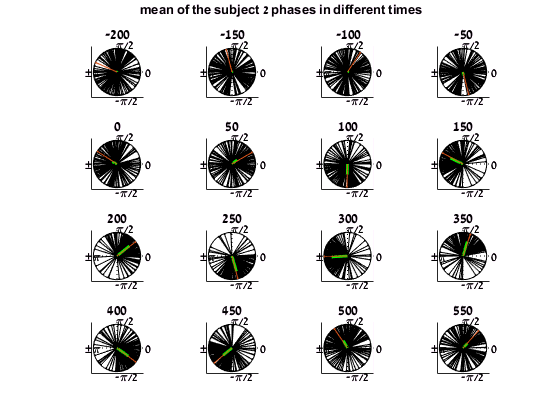

Error using subplot (line 297)
Index exceeds number of subplots.

figure;
subj_ind = 2;
t0s = -200:50:550;
for ii = 1:length(t0s)
    subplot(4,4,ii)    
    circ_plot2(theta_phases_subjects{subj_ind}(find(times>t0s(ii),1),:)','compass','-k',true,'linewidth',2,'color','g');
    hold on
    circ_plot2([erp_theta_phases(subj_ind,find(times>t0s(ii),1)) erp_theta_phases(subj_ind,find(times>t0s(ii),1))]','compass','-b', true);
    title(t0s(ii))
end
title_subplots(sprintf('mean of the subject %d phases in different times', subj_ind));

subj_ind = 8

[~,t_ind] = min(circ_std(cell2mat(theta_phases_subjects),[],[],2))

t_ind = 319

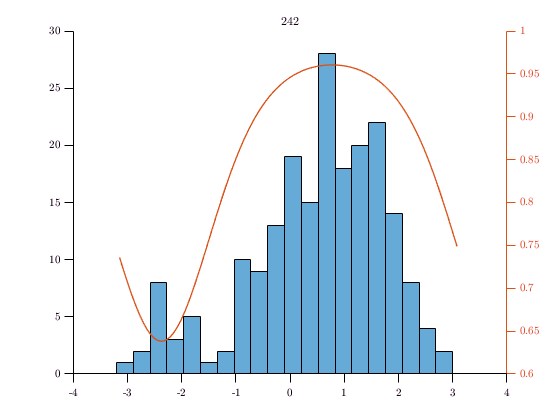

total_theta_phases = cell2mat(cellfun(@(X) X(t_ind,:),theta_phases_subjects, 'UniformOutput' ,false));
[thetahat, kappa] = circ_vmpar(total_theta_phases);
[p,a]=circ_vmpdf([], thetahat, kappa);
figure;
histogram(total_theta_phases,20)
yyaxis right
plot(a-pi,(1-p))
title([int2str(times(t_ind))])

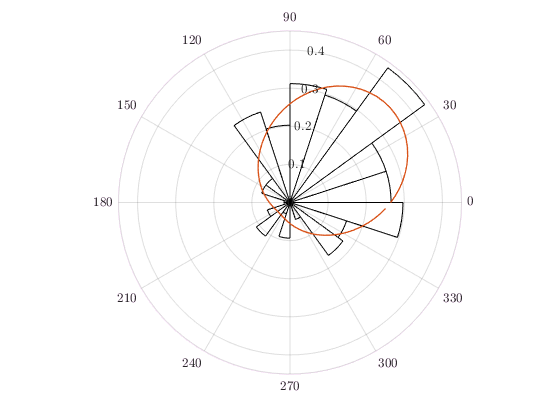


figure
polarhistogram(total_theta_phases,20,'Normalization','pdf',...
    'FaceAlpha',0)

%     'DisplayStyle','stairs')
hold on
polarplot(a,p)

% title([int2str(times(t_ind))])


freq_mean = (freq_max+freq_min)/2;
jitter_estimate = 1/sqrt(kappa) * pi/2 / freq_mean / SamplingInterval * 1e6;

fprintf('jitter estimate is %.0f [ms] at t ~ %.0f [ms]', jitter_estimate , times(t_ind))

jitter estimate is 61 [ms] at t ~ 242 [ms]

Bootstrap aprroximation of the jitter:

N = 1e5;
n = 300; % floor(length(total_theta_phases)/2); %30
total_theta_phases = cell2mat(cellfun(@(X) X(t_ind,:),theta_phases_subjects, 'UniformOutput' ,false));
randomi = randi(length(total_theta_phases), N, n);
jitter_estimates = ones(N,1);
for ii = 1:N
    [~, kappa] = circ_vmpar(total_theta_phases(randomi(ii,:)));
    jitter_estimates(ii) = kappa;
end
jitter_estimates = 1./sqrt(jitter_estimates) * pi/2 / freq_mean / SamplingInterval * 1e6;
fprintf('jitter estimate is %.0f±%.0f [ms] at t ~ %.0f', ...
    mean(jitter_estimates), prctile(jitter_estimates,97.5)-mean(jitter_estimates), times(t_ind))

jitter estimate is 86±15 [ms] at t ~ 242

## for only one subject (8)

subj = 8;
[~,t_ind_subj] = min(circ_std(theta_phases_subjects{subj},[],[],2))

t_ind_subj = 317

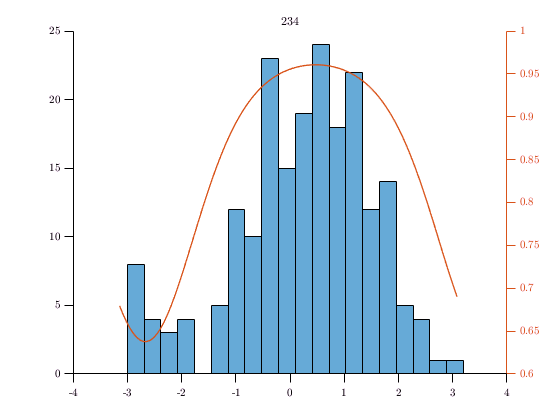

subj_theta_phases = cell2mat(cellfun(@(X) X(t_ind_subj,:),theta_phases_subjects(subj), 'UniformOutput' ,false));
[thetahat, kappa] = circ_vmpar(subj_theta_phases);
[p,a]=circ_vmpdf([], thetahat, kappa);
figure;
histogram(subj_theta_phases,20)
yyaxis right
plot(a-pi,(1-p))
title([int2str(times(t_ind_subj))])

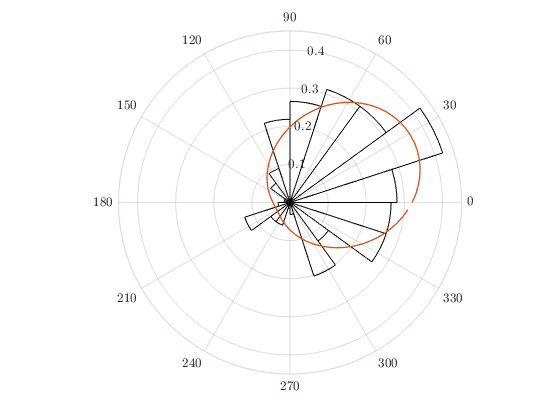


figure
polarhistogram(subj_theta_phases,20,'Normalization','pdf',...
    'FaceAlpha',0)

%     'DisplayStyle','stairs')
hold on
polarplot(a,p)

% title([int2str(times(t_ind))])


freq_mean = (freq_max+freq_min)/2;
jitter_estimate = 1/sqrt(kappa) * pi/2 / freq_mean / SamplingInterval * 1e6;

fprintf('jitter estimate is %.0f [ms] at t ~ %.0f [ms]', jitter_estimate , times(t_ind_subj))

jitter estimate is 61 [ms] at t ~ 234 [ms]

Bootstrap aprroximation of the jitter:

N = max(1e4,length(subj_theta_phases)*10);
n = floor(length(subj_theta_phases)/2); 
randomi = randi(length(subj_theta_phases), N, n);
subj_jitter_estimates = ones(N,1);
for ii = 1:N
    [~, kappa] = circ_vmpar(subj_theta_phases(randomi(ii,:)));
    subj_jitter_estimates(ii) = kappa;
end
subj_jitter_estimates = 1./sqrt(subj_jitter_estimates) * pi/2 / freq_mean / SamplingInterval * 1e6;
fprintf('jitter estimate is %.0f±%.0f [ms] at t ~ %.0f', ...
mean(subj_jitter_estimates), prctile(subj_jitter_estimates,97.5)-mean(subj_jitter_estimates), times(t_ind_subj))

jitter estimate is 61±10 [ms] at t ~ 234

## Aproximation of the jitter for all subjects

jitter_estimates = ones(1,N_subjects);
for subj = 1:N_subjects
    [~,t_ind_subj] = min(circ_std(theta_phases_subjects{subj},[],[],2)+100*(times'<0));
    subj_theta_phases = cell2mat(cellfun(@(X) X(t_ind_subj,:),theta_phases_subjects(subj), 'UniformOutput' ,false));
    [thetahat, kappa] = circ_vmpar(subj_theta_phases);
    jitter_estimate = 1/sqrt(kappa) * pi/2 / freq_mean / SamplingInterval * 1e6;
    jitter_estimates(subj) = jitter_estimate;
end
fprintf('jitter estimate is %.0f±%.0f [ms]', ...
mean(jitter_estimates), std(jitter_estimates))

jitter estimate is 77±18 [ms]

## comparing alignemnt

t_ind = find(times>150,1);
freq_inds = find(freqs>4.5 & freqs < 8.2);

phase_shift = [];
for ii = 1:length(times)
    phase_shift = [phase_shift; get_phase_shift(squeeze(total_phases), ii, freq_inds, freqs, SamplingInterval)'/srate];
end

figure;
varplot(times,abs(phase_shift)/srate)
xlabel t[ms]
ylabel 'mean abs shift[ms]'
title 'mean abs shift (4.5-8.1 Hz)'

## Max ERP

## Hilbert transform

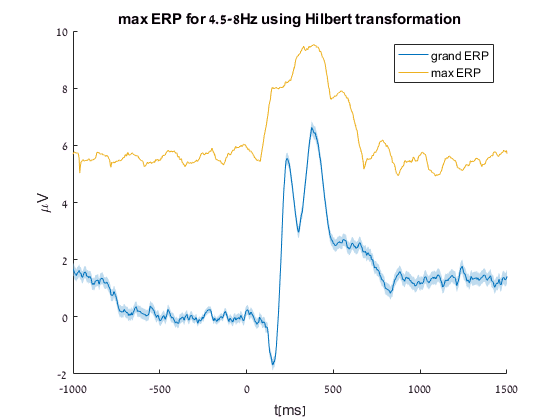

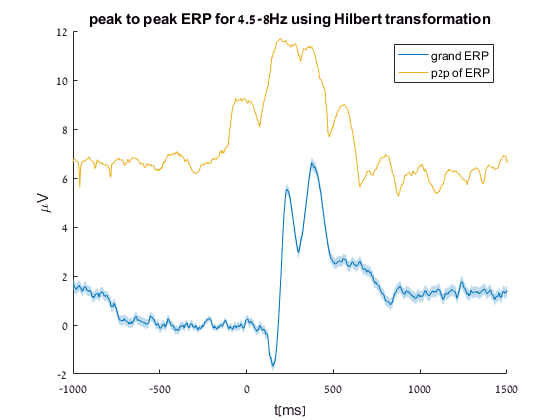

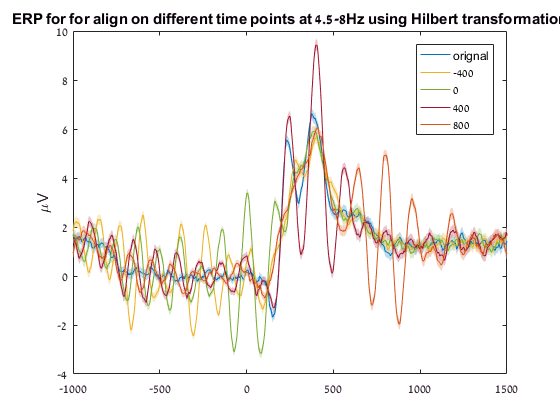

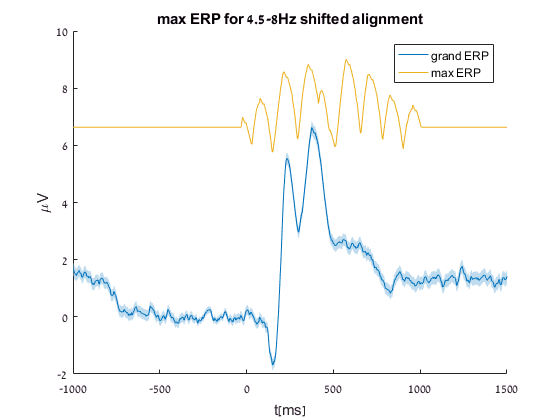

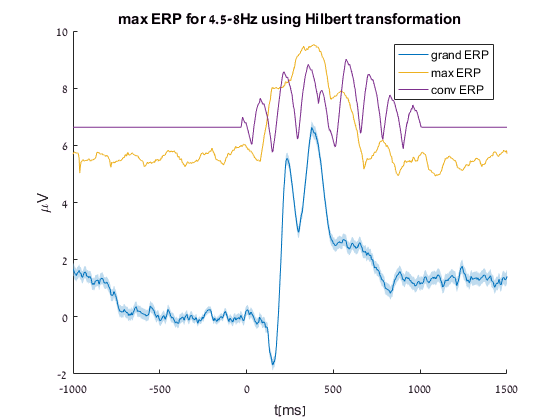

show_aligned_ERP(norm_trials, 4.5, 8, SamplingInterval, times)

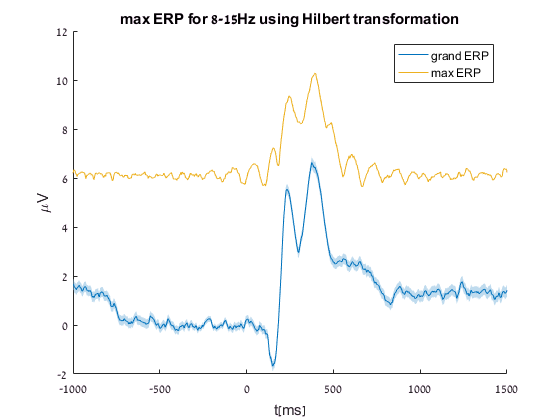

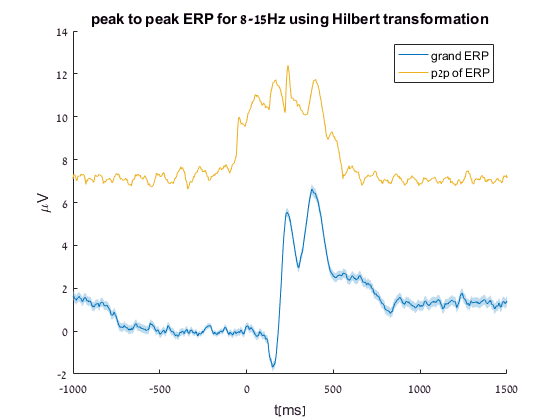

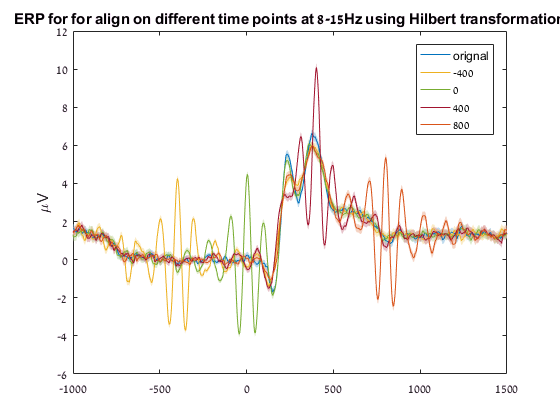

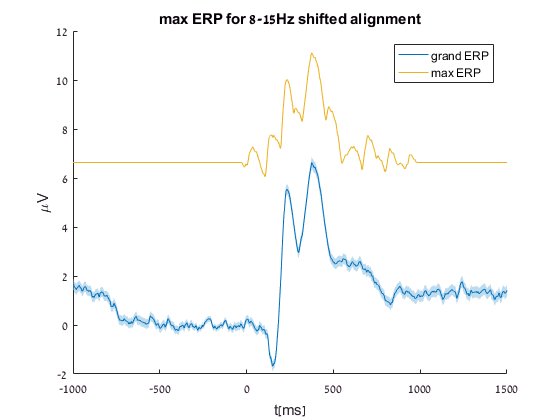

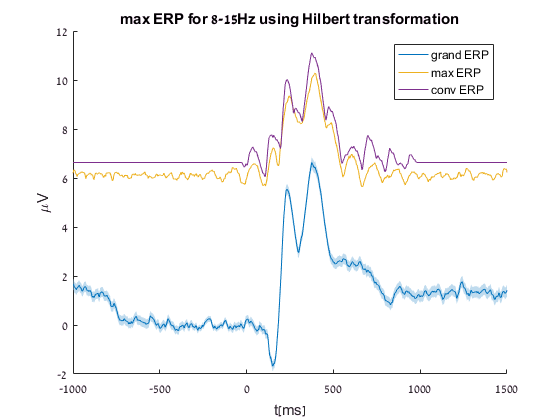

show_aligned_ERP(norm_trials, 8, 15, SamplingInterval, times)

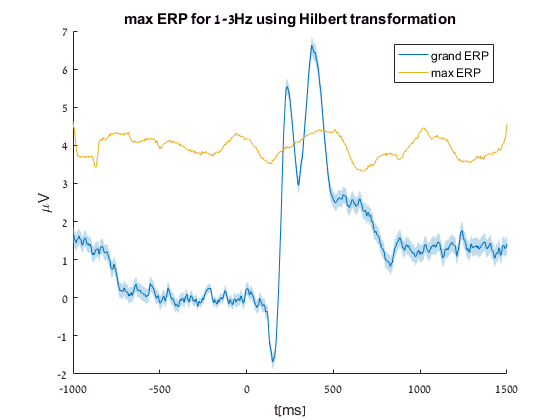

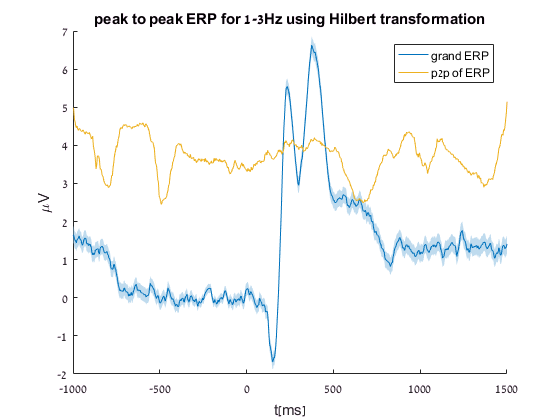

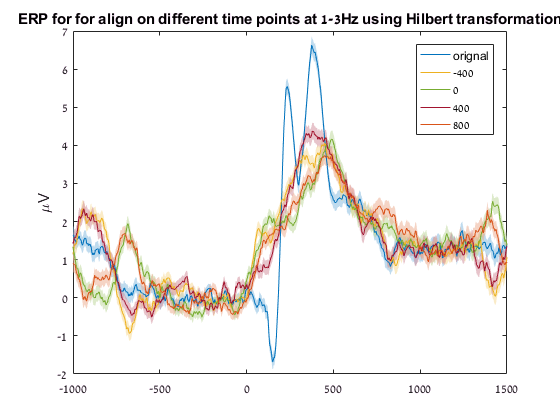

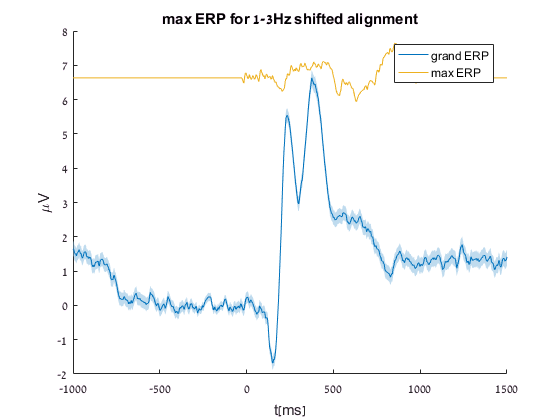

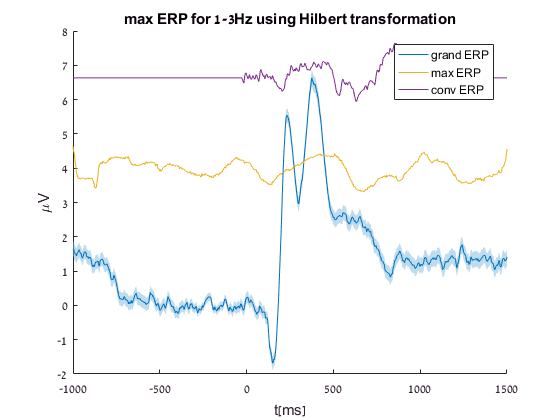

show_aligned_ERP(norm_trials, 1, 3, SamplingInterval, times)

## Example for aligned

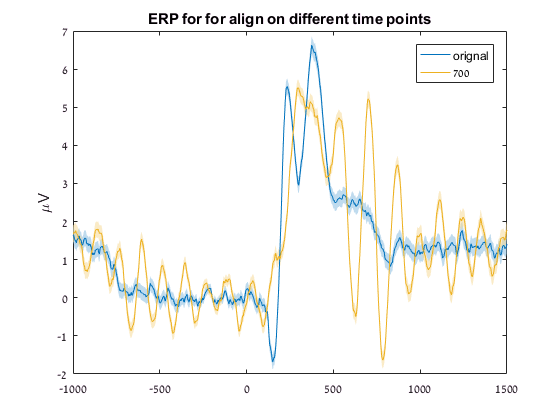

figure 
t_aligned = 700;
varplot(times,squeeze(norm_trials))
hold on
for ii = t_aligned
    varplot(times,align_trials_by_shift(norm_trials, total_phase_shifts(find(times>ii,1),:)));
end
legend(['orignal', string(t_aligned)])
ylabel '\muV'
title 'ERP for for align on different time points'

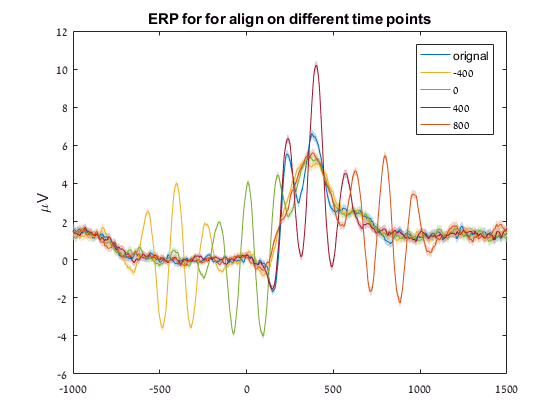

figure;
freq_inds = find(freqs>4.5 & freqs < 8);
varplot(times,squeeze(norm_trials))
hold on
for ii = -400:400:800
    varplot(times,squeeze(align_trials_by_shift(norm_trials, get_phase_shift(squeeze(total_phases), find(times>ii,1),freq_inds, freqs, SamplingInterval)')))
end
legend(['orignal', string(-400:400:800)])
ylabel '\muV'
title 'ERP for for align on different time points'

## And now for different frequency band

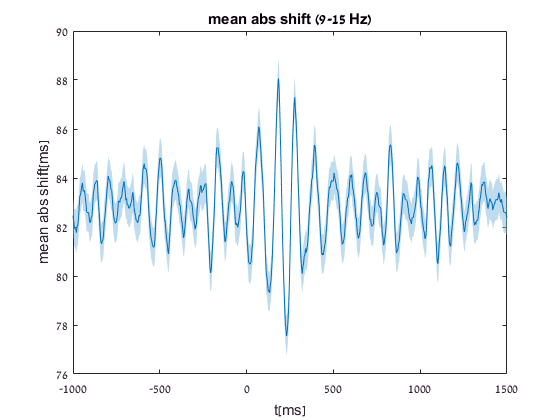

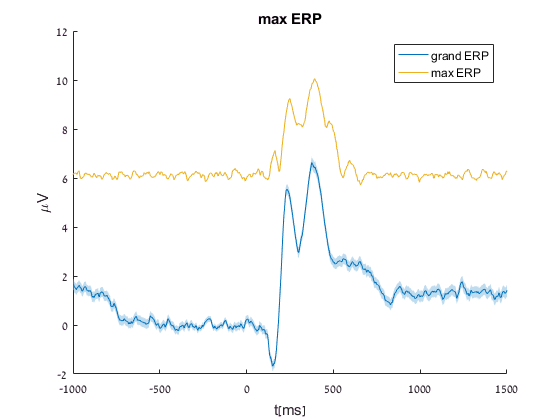

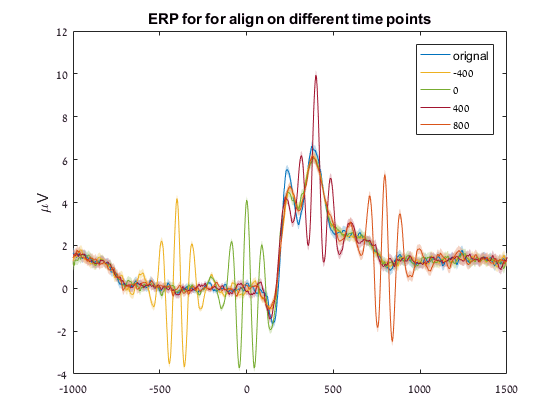

t_ind = find(times>150,1);
freq_inds = find(freqs>9 & freqs < 15);

phase_shift = [];
for ii = 1:length(times)
    phase_shift = [phase_shift; get_phase_shift(squeeze(total_phases), ii,freq_inds, freqs, SamplingInterval)'/srate];
end

figure;

varplot(times,abs(phase_shift)/srate)
xlabel t[ms]
ylabel 'mean abs shift[ms]'
title 'mean abs shift (9-15 Hz)'

max_p3=zeros(size(times));
for ii = 1:length(times)
    mean_aligned = mean(squeeze(align_trials_by_shift(norm_trials, get_phase_shift(squeeze(total_phases), ii, freq_inds, freqs, SamplingInterval))),2);
    max_p3(ii) = max(mean_aligned(times>0 & times<500));
end

figure;
varplot(times,squeeze(norm_trials))
hold on
for ii = -400:400:800
    varplot(times,squeeze(align_trials_by_shift(norm_trials, get_phase_shift(squeeze(total_phases), find(times>ii,1),freq_inds, freqs, SamplingInterval))))
end
legend(['orignal', string(-400:400:800)])
ylabel '\muV'
title 'ERP for for align on different time points'




freq_ind = 11;
diff_phases = angdiff(total_phases,total_sub_phases);
phases = squeeze(diff_phases(1,freq_ind,:,:));
hist_phases = zeros(1,size(phases,1));
count_phases = zeros(1,size(phases,1));
for ii=1:size(phases,2)    
    pos = 1+find(diff(phases(:,ii),1,1) < -1);
    for jj=1:length(pos)-1
        hist_phases(pos(jj)) = hist_phases(pos(jj)) + pos(jj+1)-pos(jj);
        count_phases(pos(jj)) = count_phases(pos(jj)) + 1;
    end
end
hist_phases = hist_phases./count_phases;

hist_phases_var = zeros(1,size(phases,1));
for ii=1:size(phases,2)    
    pos = 1+find(diff(phases(:,ii),1,1) < -1);
    for jj=1:length(pos)-1
        hist_phases_var(pos(jj)) = hist_phases_var(pos(jj)) + abs(pos(jj+1)-pos(jj) - hist_phases(pos(jj)))^2;
    end
end
hist_phases_var = hist_phases_var./count_phases;


function show_aligned_ERP(norm_trials, min_freq, max_freq, SamplingInterval, times)
max_p3=zeros(size(times));
p2p_max=max_p3;
total_phase_shifts = get_hilbert_phase_shift(norm_trials, min_freq, max_freq, SamplingInterval);
for ii = 1:length(times)
    mean_aligned = mean(align_trials_by_shift(norm_trials, total_phase_shifts(ii,:)),2);
    max_p3(ii) = max(mean_aligned(times>0 & times<500));
    p2p_max(ii) = max(mean_aligned(times>240 & times<450)) - min(mean_aligned(times>0 & times<450));
end

figure;
hold on
varplot(times,squeeze(norm_trials))
plot(times,max_p3)
legend({'grand ERP','max ERP'})
xlabel t[ms]
ylabel '\muV'
title(sprintf('max ERP for %.2g-%.2gHz using Hilbert transformation', min_freq, max_freq))

figure;
hold on
varplot(times,squeeze(norm_trials))
plot(times,p2p_max)
legend({'grand ERP','p2p of ERP'})
xlabel t[ms]
ylabel '\muV'
title(sprintf('peak to peak ERP for %.2g-%.2gHz using Hilbert transformation', min_freq, max_freq))

figure;
varplot(times,squeeze(norm_trials))
hold on
for ii = -400:400:800    
    varplot(times,align_trials_by_shift(norm_trials, total_phase_shifts(find(times>ii,1),:))); 
end
legend(['orignal', string(-400:400:800)])
ylabel '\muV'
title(sprintf('ERP for for align on different time points at %.2g-%.2gHz using Hilbert transformation', min_freq, max_freq))

conv_erp = conv_noise(norm_trials, min_freq, max_freq, SamplingInterval, times, -400, false);

% figure;
% permutest_plot( max_p3, repmat(conv_erp, size(max_p3,1)), [], 0.01, 1e4, true, [], times, false)
% plot(times, max_p3 - conv_erp)

figure;
hold on
varplot(times,squeeze(norm_trials))
plot(times,max_p3)
plot(times,conv_erp)

legend({'grand ERP','max ERP', 'conv ERP'})
xlabel t[ms]
ylabel '\muV'
title(sprintf('max ERP for %.2g-%.2gHz using Hilbert transformation', min_freq, max_freq))

end

function max_p3 = conv_noise(norm_trials, min_freq, max_freq, SamplingInterval, times, t0, show)
    
set_default('show', true);
       
total_phase_shifts = get_hilbert_phase_shift(norm_trials, min_freq, max_freq, SamplingInterval);
mean_aligned = mean(align_trials_by_shift(norm_trials, total_phase_shifts(find(times>t0,1),:)),2);   
grand_erp = mean(squeeze(norm_trials),2);
noise = mean_aligned - grand_erp;
noise(times>0) = 0;

% figure;
% plot(times, noise)
% hold on 
% plot(times, circshift(noise,1 - find(times>t0,1)))

max_p3=zeros(size(times));
for ii = 1:length(times)
    noise_shift = circshift(noise,ii - find(times>t0,1)) + grand_erp;
    max_p3(ii) = max(noise_shift(times>0 & times<500));
%     mean_aligned = mean(align_trials_by_shift(norm_trials, total_phase_shifts(ii,:)),2);    
end
  

figure;
hold on
varplot(times,squeeze(norm_trials))
plot(times,max_p3)
legend({'grand ERP','max ERP'})
xlabel t[ms]
ylabel '\muV'
title(sprintf('max ERP for %.2g-%.2gHz shifted alignment', min_freq, max_freq))
end

function u = mean_angle(phi,dim)
    
	u = angle(mean(exp(1i*phi),dim));
end
